# Simulation of confidence intervals

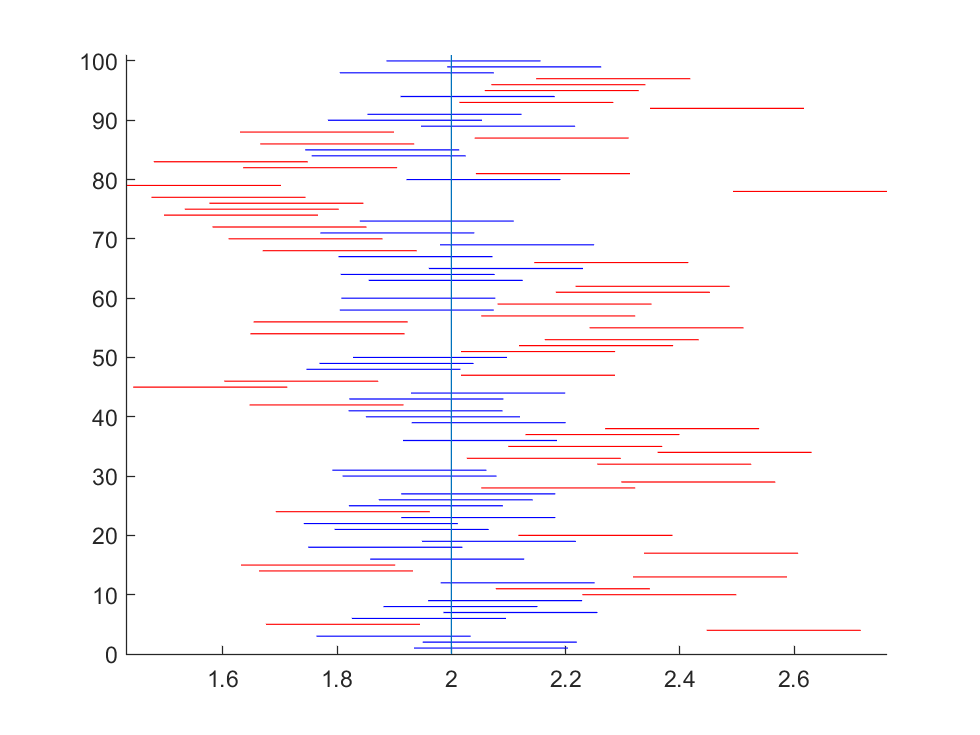

% Params:
n = 25;
mu = 2;
sigma = 1;
alpha = 00.5;

x = normrnd(mu, sigma, n, 100);
xbar = mean(x);
lowerl =  xbar - norminv(1-alpha/2)*sigma/sqrt(n);
upperl =  xbar + norminv(1-alpha/2)*sigma/sqrt(n);

figure(1)
hold on
for k=1:100
    if upperl(k) < mu
        plot([lowerl(k) upperl(k)], [k k], 'r')
    elseif lowerl(k) > mu
        plot([lowerl(k) upperl(k)],[k k],'r')
    else
        plot([lowerl(k) upperl(k)], [k k], 'b')
    end
end

b1 = min(xbar - norminv(1-alpha/2)*sigma/sqrt(n));
b2 = max(xbar + norminv(1-alpha/2)*sigma/sqrt(n));
axis([b1 b2 0 101])

plot([mu mu], [0 101])
hold off

##  Maximum likelihood/Least squares

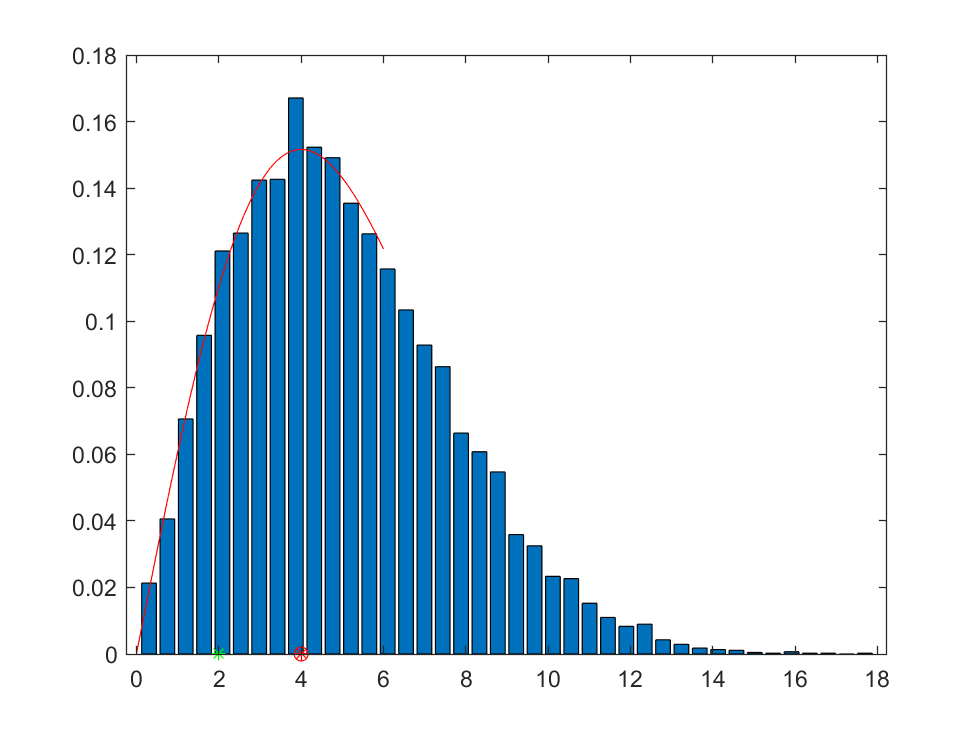

M = 1e4;
b = 4;
x = raylrnd(b, M, 1);
hist_density(x, 40)
hold on
my_est_ml = 4; %ML
my_est_ls = 2; %LS
plot(my_est_ml, 0, 'r*')
plot(my_est_ls, 0, 'g*')
plot(b, 0, 'ro')
plot(0:0.1:6, raylpdf(0:0.1:6, my_est_ml), 'r')
hold off

## Confidence interval for Rayleigh distribution

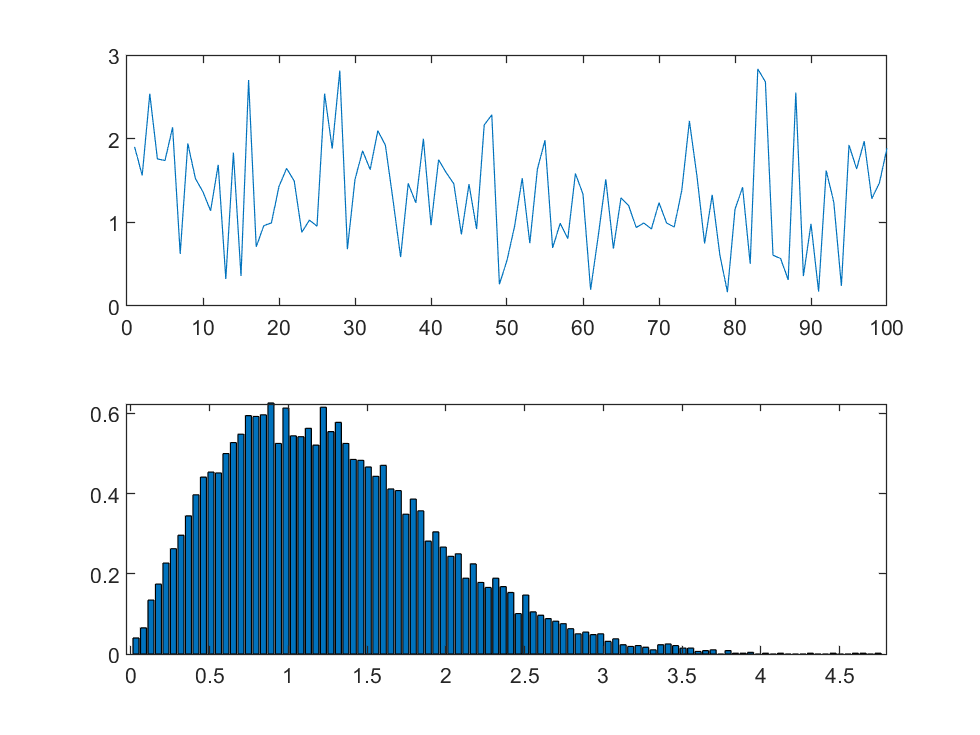

load wave_data.mat
subplot(211), plot(y(1:100))
subplot(212), hist_density(y)
lower_bound = 2;
upper_bound = 4;
my_est = 10;
hold on
%plot(lower_bound, 0, 'g*')
%plot(upper_bound, 0, 'g*')
%plot(0:0.1:6, raylpdf(9:0.1:6, my_est), 'r')
hold off

## Distributions of given data

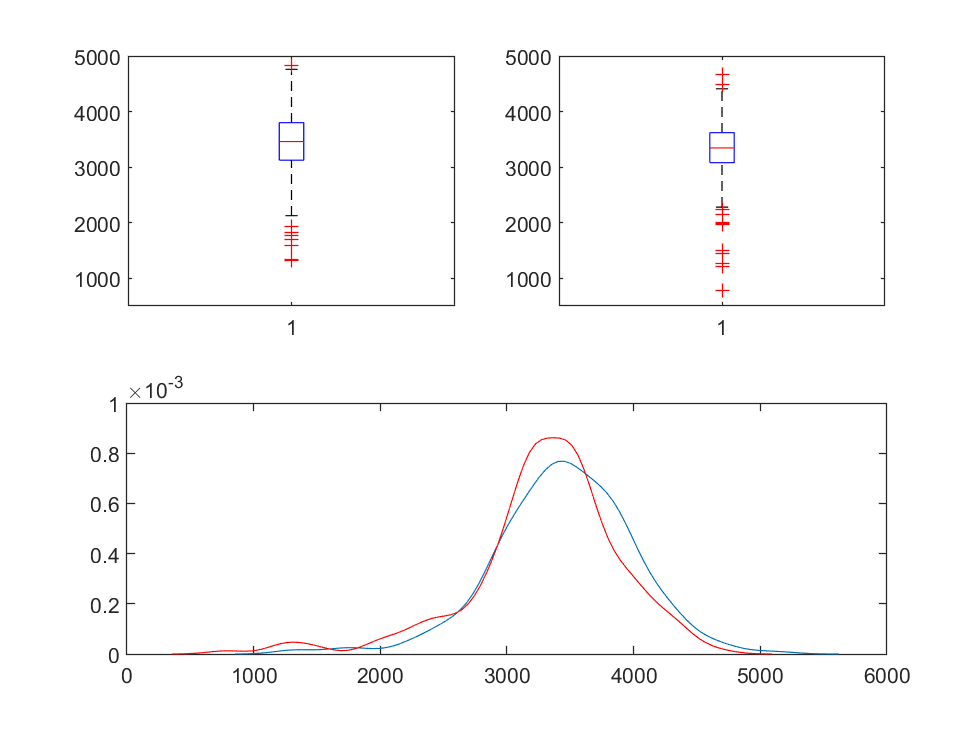

load birth.dat


x = birth(birth(:, 20) < 3, 3);
y = birth(birth(:, 20) == 3, 3);

subplot(2,2,1), boxplot(x),
axis([0 2 500 5000])
subplot(2,2,2), boxplot(y),
axis([0 2 500 5000])

subplot(2,2,3:4), ksdensity(x),
hold on
[fy, ty] = ksdensity(y);
plot(ty, fy, 'r')
hold off

## Testing for normality

%jbtest()

## Regression

%res = X*beta_hat - y1;
%subplot(2,1,1), normplot(res)
%subplot(2,1,2), hist(res)

## Multiple linear regression